# **Analysis for sniff signals collected using thermistor implant**

## Reading in sniff data

folderpath = ("\\F-moving-data\shnk3 (a)\Sniff\Data");
ntraces = 1;
nmice =2;
data = zeros(2881000,nmice,ntraces);
for mouse = 1:nmice
    mousepath = folderpath + '\' + (2196 + mouse);
    for trace = 1:ntraces
        datapath = mousepath + '\' + trace;
        cd(datapath)
        sniffpile = dir('NiDAQ_sniff.dat');
        cd(sniffpile.folder)
        sniff_file = fopen(sniffpile.name,'r');
        sniff=fread(sniff_file,'float64');
        sniff=sniff(1:4:length(sniff)); %analog sniff trace is every fourth entry
        data(:,mouse, trace) = sniff;
    end
end

mouse_names = {'Mouse 2197', 'Mouse 2198'};
signal_names = {'Signal 1', 'Signal 2', 'Signal 3'};

dims = size(data);
fprintf('Loaded Data:\n%g mice\n%g signals per mouse', length(data(1,:,1)), length(data(1,1,:)))

Loaded Data:
2 mice
1 signals per mouse

## Smoothing and Plotting

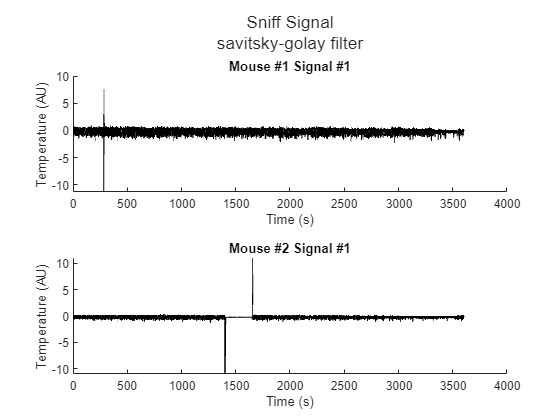

%sampling frequency
f = 800;

%smoothing parameter
smoo = 25;
for mouse = 1:nmice
    for trace = 1:ntraces
        data(:,mouse, trace) = smooth(data(:,mouse,trace),smoo,'sgolay');
    end
end

%graphing
figure;
tiledlayout(nmice, ntraces)
times=(1:length(data))./f;
for mouse = 1:nmice
    for trace = 1:ntraces
        nexttile;
        hold on
        plot(times,data(:,mouse,trace),'k-','LineWidth',1)
        ylabel('Temperature (AU)')
        xlabel('Time (s)')
        title(sprintf('Mouse #%d Signal #%d', mouse, trace));
        hold off
    end
end
title1 = {'Sniff Signal', 'savitsky-golay filter'};
sgtitle(title1);

## Removing outliers

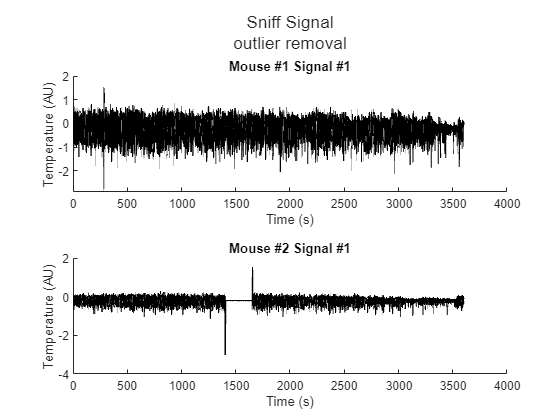

pos_outlier_amplitude = 1.5;
neg_outlier_amplitude = -3;

for mouse = 1:nmice
    for trace = 1:ntraces
        outliers = (data(:, mouse, trace) > pos_outlier_amplitude) | (data(:, mouse, trace) < neg_outlier_amplitude);
        data(outliers, mouse, trace) = 0;
    end
end

%graphing
figure;
tiledlayout(nmice, ntraces)
times=(1:length(data))./f;
for mouse = 1:nmice
    for trace = 1:ntraces
        nexttile;
        hold on
        plot(times,data(:,mouse,trace),'k-','LineWidth',1)
        ylabel('Temperature (AU)')
        xlabel('Time (s)')
        title(sprintf('Mouse #%d Signal #%d', mouse, trace));
        hold off
    end
end
title1 = {'Sniff Signal', 'outlier removal'};
sgtitle(title1);

## Padding dropped signal with zeros

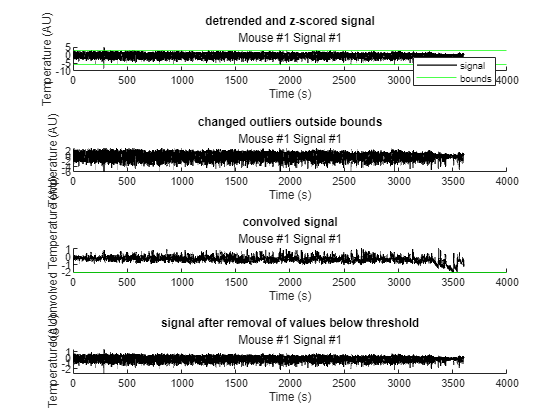

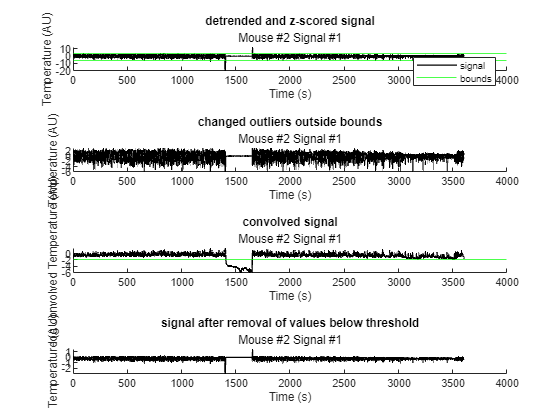

window = f;
u = ones(window, 1)/(window);
threshold = -2;
upper_bound = 3;
lower_bound = -6;

for mouse = 1:nmice
    for trace = 1:ntraces

        
        figure;
        tiledlayout(4,1);


        zdata = zscore(detrend(data(:,mouse,trace)));

        nexttile;
        hold on
        plot(times, zdata,'k-','LineWidth',1)
        ylabel('Temperature (AU)')
        xlabel('Time (s)')
        yline(upper_bound, 'Color' , 'green');
        yline(lower_bound, 'Color' , 'green');
        title('detrended and z-scored signal')
        subtitle(sprintf('Mouse #%d Signal #%d', mouse, trace))
        legend('signal','bounds')
        hold off


        zdata(zdata > upper_bound) = upper_bound;
        zdata(zdata < lower_bound) = lower_bound;

        nexttile;
        hold on
        plot(times,(zdata),'k-','LineWidth',1)
        ylabel('Temperature (AU)')
        xlabel('Time (s)')
        title('changed outliers outside bounds')
        subtitle(sprintf('Mouse #%d Signal #%d', mouse, trace))
        hold off
        
        

        conv_data = log(conv(abs(zdata), u, "same"));


        nexttile;
        hold on
        plot(times,conv_data,'k-','LineWidth',1)
        yline(threshold, 'Color', 'green')
        ylabel('log convolved Temperature (AU)')
        xlabel('Time (s)')
        title('convolved signal')
        subtitle(sprintf('Mouse #%d Signal #%d', mouse, trace))
        hold off
  
        % changing values below threshold to zero
        ind_below = conv_data < threshold;
        data(ind_below,mouse,trace) = 0;

        nexttile;
        hold on
        plot(times,data(:,mouse,trace),'k-','LineWidth',1)
        ylabel('Temperature (AU)')
        xlabel('Time (s)')
        title('signal after removal of values below threshold')
        subtitle(sprintf('Mouse #%d Signal #%d', mouse, trace))
        hold off
        pause(0.1)

    end
end

## Locating peaks and corresponding inhale/exhale times

Dividing signal into 5 second windows, Z-scoring whithin those windows, and using findpeaks

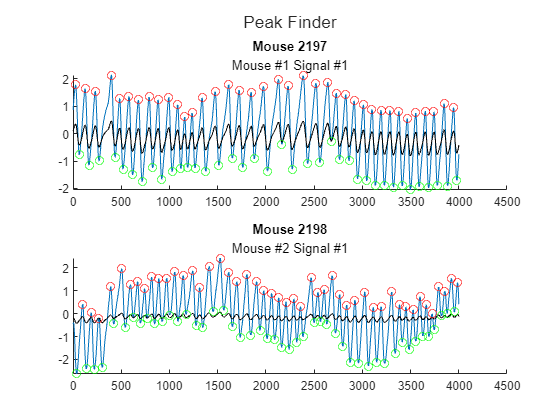

sniff_frequencies = cell(nmice, ntraces);
inhalations_times_seconds = cell(nmice, ntraces);
zniff = zeros(4001, nmice, ntraces);



tic
figure;
tiledlayout(nmice,ntraces)
for mouse = 1:nmice
    for trace=1:ntraces
        inhale_times = [];
        exhale_times = [];
        if ~isempty(data(:,mouse,trace))
            windows = round(1:(5*f):length(data(:,mouse,trace)));
            for scan = 2:length(windows)
        
                time_stamp=(windows(scan-1)):windows(scan);% time stamps whithin the window
        
                zniff(:,mouse,trace)=zscore(data(time_stamp,mouse,trace));%z-scoring within that window
        
        
                [sniff_pks,in_locs] = findpeaks(zniff(:,mouse,trace),'MinPeakDistance',smoo,'MinPeakProminence',0.5); %find inhalation points
                [ex_pks,ex_locs] = findpeaks(-zniff(:,mouse,trace),'MinPeakDistance',smoo,'MinPeakProminence',0.5); %find exhalation points
                
        
                %visual validation of peak finder
                if scan == 5
                    nexttile;
                    hold on
                    
                    plot(zniff(:,mouse,trace))
                    plot(data(time_stamp,mouse,trace), "Color" , "Black")
                    plot(in_locs,zniff(in_locs,mouse,trace),'ro')
                    plot(ex_locs,zniff(ex_locs,mouse,trace),'go')
                    title(sprintf(mouse_names{mouse}))
                    subtitle(sprintf('Mouse #%d Signal #%d', mouse, trace))
                    hold off
                end
        
                for peak= 1:length(in_locs)
                    inhale=in_locs(peak);
        
                    exhale=ex_locs(ex_locs>inhale);
                    if ~isempty(exhale)
        
                        inhale_times=[inhale_times; inhale + windows(scan-1)];
                        exhale_times=[exhale_times; exhale + windows(scan-1)];
                        sniff_frequencies{mouse,trace} = f./diff(inhale_times);
                        inhalations_times_seconds{mouse,trace} =inhale_times(2:end)./f;
                                      
                    end
        
                end
        
            end
        end
    end
end
sgtitle('Peak Finder');

toc

Elapsed time is 39.460560 seconds.


## Concatenating signals within mice

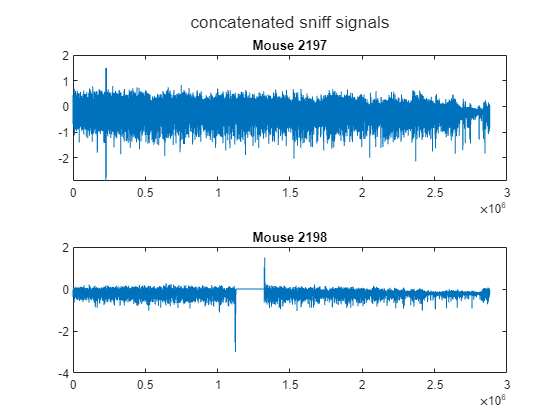

conc_sniff = [data(:, :, 1)];

figure;
tiledlayout(nmice,1)
for mouse = 1:nmice
    nexttile;
    plot(conc_sniff(:,mouse))
    title(mouse_names{mouse})
end
sgtitle('concatenated sniff signals')

## Finding sniff frequencies across time

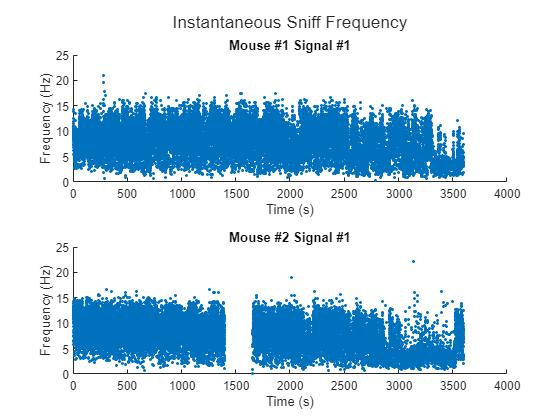

figure;
tiledlayout(nmice, ntraces)
for mouse = 1:nmice
    for trace = 1:ntraces
        nexttile;
        scatter(inhalations_times_seconds{mouse,trace}, sniff_frequencies{mouse,trace}, 5, 'filled');
        xlabel('Time (s)');
        ylabel('Frequency (Hz)')
        title(sprintf('Mouse #%d Signal #%d', mouse, trace))
    end
end  
sgtitle('Instantaneous Sniff Frequency')

## Concatenating frequencies

conc_freq = cell(nmice,1);
for mouse = 1 :nmice
    conc_freq{mouse,1} = [sniff_frequencies{mouse, 1}; sniff_frequencies{mouse, 2}; sniff_frequencies{mouse, 3}];
end

figure;
tiledlayout(nmice, 1)
for mouse = 1:nmice
    nexttile;
    scatter(conc_freq{mouse,1}, 5, 'filled');
    xlabel('Time (s)');
    ylabel('Frequency (Hz)')
    title(sprintf('Mouse #%d', mouse))   
end  
sgtitle('Instantaneous Sniff Frequency')


## Dynamics of sniff frequency across time

smooth_sniff_frequencies = cell(nmice, ntraces);

figure;
tiledlayout(nmice, ntraces)
for mouse = 1:nmice
    for trace = 1:ntraces
        nexttile;

        hold on
        plot(inhalations_times_seconds{mouse,trace}, sniff_frequencies{mouse,trace})

        % Simple Moving Average
        binsize = f/10;
        coeff = ones(1, binsize)/binsize;

        smfreq = filter(coeff, 1, sniff_frequencies{mouse,trace});
        smooth_sniff_frequencies{mouse,trace} = smfreq;
        plot(inhalations_times_seconds{mouse,trace},smooth_sniff_frequencies{mouse,trace})
        
        legend('instantaneous frequency', 'simple moving average')
        xlabel('Time (s)')
        ylabel('Frequency (Hz)')
        hold off
    end
end


## Estimating the autocovariance/correlation and cross-covariance/correlation functions:

%length of time series
M = length(times);

%number of sniff signals
n = 1;

%maximum lag in seconds
tiledlayout(nmice, ntraces)

max_lag = 10;


propogating an nmice x ntraces x nmice x ntraces cell array containing autocovariance functions for all possible combinations of mice and signals

ACVs = cell(nmice, ntraces, nmice, ntraces);
lags = cell(nmice, ntraces, nmice, ntraces);

for mouse = 1:nmice
    for trace = 1:ntraces
        for cross_mouse = 1:nmice
            for cross_trace = 1:ntraces
                [ACVs{mouse,trace,cross_mouse, cross_trace}, lags{mouse,trace,cross_mouse, cross_trace}] = ...
                    xcov(sniff_frequencies{mouse, trace}, sniff_frequencies{cross_mouse, cross_trace}, floor(max_lag * f), 'none');
                lags{mouse,trace,cross_mouse,cross_trace} = lags{mouse,trace,cross_mouse, cross_trace}/f;
            end
        end
    end
end


Plotting the autocovariance functions

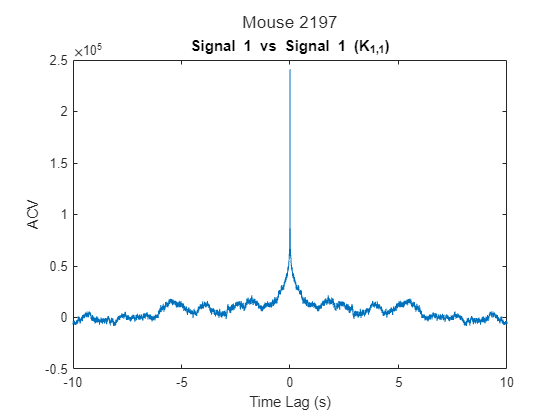

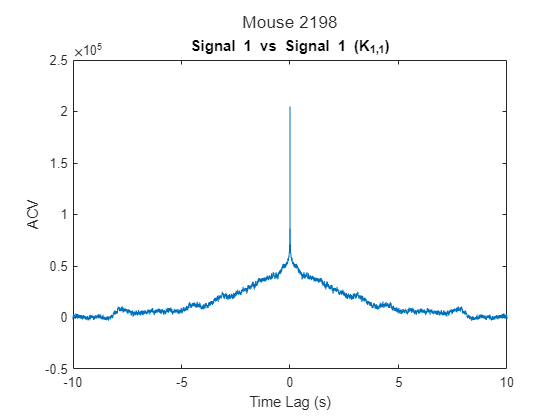

for mouse = 1:nmice
    figure;
    t = tiledlayout(ntraces, ntraces);
    for trace = 1:ntraces
        for cross_trace = 1:ntraces
        
            nexttile;
            plot(lags{mouse,trace,mouse,cross_trace}, ACVs{mouse,trace,mouse,cross_trace});
            title(sprintf('%s vs %s (K_{%d,%d})',...
                signal_names{trace},signal_names{cross_trace},trace,cross_trace))
            xlabel('Time Lag (s)')
            ylabel('ACV')
        
        end
    end
    sgtitle(mouse_names{mouse})
end

Autocorrelation function

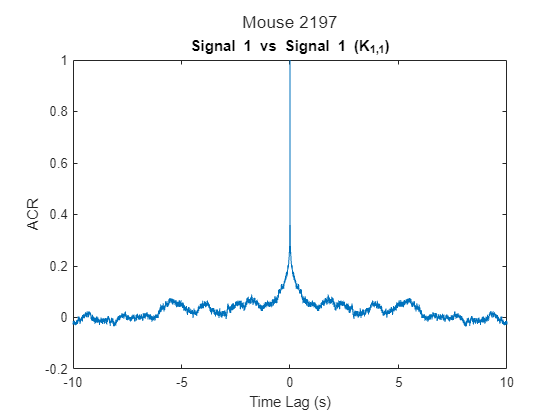

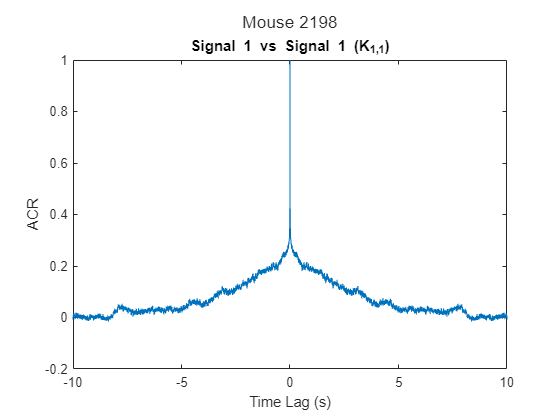

lag0 = zeros(1,1,1,1);
ACRs = cell(nmice, ntraces, nmice, ntraces);
for mouse = 1:nmice
    for trace = 1:ntraces
        for cross_mouse = 1:nmice
            for cross_trace = 1:ntraces

                lag0(mouse, trace, cross_mouse, cross_trace) = ...
                    find(lags{mouse, trace, cross_mouse, cross_trace} == 0);

                ACRs{mouse, trace, cross_mouse, cross_trace} = ...
                    ACVs{mouse, trace, cross_mouse, cross_trace} ...
                    / ACVs{mouse, trace, cross_mouse, cross_trace}(lag0(mouse, trace, cross_mouse, cross_trace));
            end
        end
    end
end

for mouse = 1:nmice
    figure;
    t = tiledlayout(ntraces, ntraces);
    for trace = 1:ntraces
        for cross_trace = 1:ntraces
        
            nexttile;
            plot(lags{mouse,trace,mouse,cross_trace}, ACRs{mouse,trace,mouse,cross_trace});
            title(sprintf('%s vs %s (K_{%d,%d})',...
                signal_names{trace},signal_names{cross_trace},trace,cross_trace))
            xlabel('Time Lag (s)')
            ylabel('ACR')
        
        end
    end
    sgtitle(mouse_names{mouse})
end

## PSD sniff frequency time series

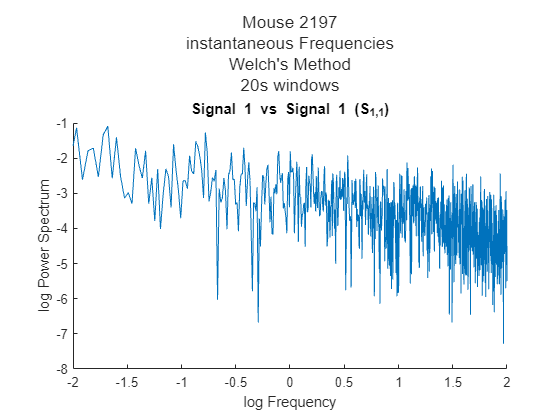

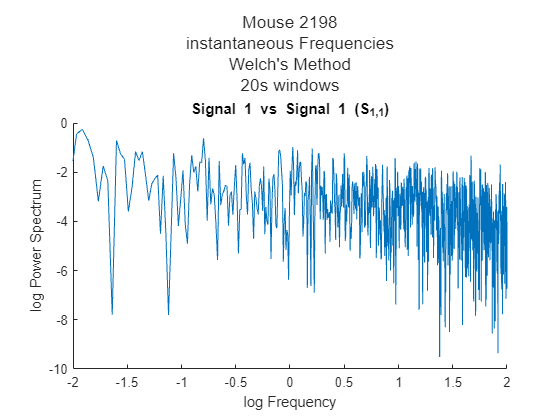


noverlap = 10*f;
L = 20*f;
PSD = cell(nmice, ntraces, nmice, ntraces);
angular_frequencies = cell(nmice, ntraces, nmice, ntraces);


for mouse = 1:nmice
    for trace = 1:ntraces
        for cross_mouse = 1:nmice
            for cross_trace = 1:ntraces

                signal1 = sniff_frequencies{mouse, trace};
                signal2 = sniff_frequencies{cross_mouse, cross_trace};
                
                % Check the lengths of the signals and zero-pad the shorter signal if necessary
                len1 = length(signal1);
                len2 = length(signal2);
                if len1 < len2
                    signal1 = [signal1; zeros(len2-len1, 1)];
                elseif len2 < len1
                    signal2 = [signal2; zeros(len1-len2, 1)];
                end

                [PSD{mouse, trace, cross_mouse, cross_trace},...
                angular_frequencies{mouse, trace, cross_mouse, cross_trace}] =...
                cpsd(signal1, signal2, hamming(L), noverlap, [], f);
   
            end
        end
    end
end

for mouse = 1:nmice
    figure;
    t = tiledlayout(ntraces, ntraces);
    for trace = 1:ntraces
        for cross_trace = 1:ntraces
            nexttile;
            hold on
            plot(log(angular_frequencies{mouse, trace, mouse, cross_trace}/(2*pi)), log(abs(PSD{mouse, trace, cross_mouse, cross_trace})))
            title(sprintf('%s vs %s (S_{%d,%d})',...
                signal_names{trace},signal_names{cross_trace},trace,cross_trace))
            ylabel("log Power Spectrum")
            xlabel('log Frequency')
            xlim([-2 2])
            hold off
        
        end
    end
    PSDtitle = {mouse_names{mouse}, 'instantaneous Frequencies', "Welch's Method" , '20s windows'};
    sgtitle(PSDtitle)
end

## ACR smoothed signals

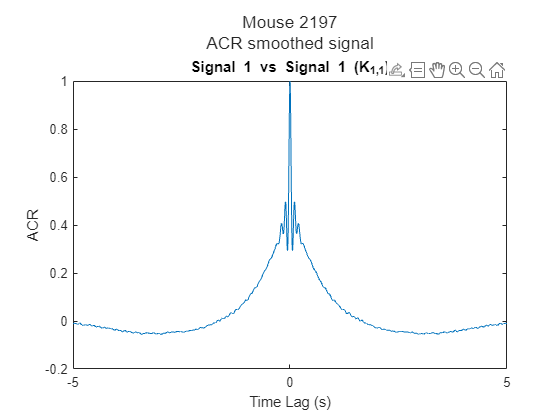

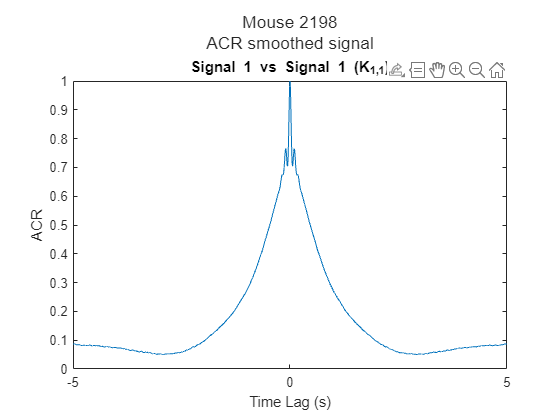

sACVs = cell(nmice, ntraces, nmice, ntraces);
slags = cell(nmice, ntraces, nmice, ntraces);

for mouse = 1:nmice
    for trace = 1:ntraces
        for cross_mouse = 1:nmice
            for cross_trace = 1:ntraces
                [sACVs{mouse,trace,cross_mouse, cross_trace}, slags{mouse,trace,cross_mouse, cross_trace}] = ...
                    xcov(data(:,mouse,trace), data(:, cross_mouse, cross_trace), floor(max_lag * f), 'none');
                lags{mouse,trace,cross_mouse,cross_trace} = lags{mouse,trace,cross_mouse, cross_trace}/f;
            end
        end
    end
end

slag0 = zeros(1,1,1,1);
sACRs = cell(nmice, ntraces, nmice, ntraces);
for mouse = 1:nmice
    for trace = 1:ntraces
        for cross_mouse = 1:nmice
            for cross_trace = 1:ntraces

                slag0(mouse, trace, cross_mouse, cross_trace) = ...
                    find(lags{mouse, trace, cross_mouse, cross_trace} == 0);

                sACRs{mouse, trace, cross_mouse, cross_trace} = ...
                    sACVs{mouse, trace, cross_mouse, cross_trace} ...
                    / sACVs{mouse, trace, cross_mouse, cross_trace}(slag0(mouse, trace, cross_mouse, cross_trace));
            end
        end
    end
end

for mouse = 1:nmice
    figure;
    t = tiledlayout(ntraces, ntraces);
    for trace = 1:ntraces
        for cross_trace = 1:ntraces
        
            nexttile;
            plot(slags{mouse,trace,mouse,cross_trace}/f, sACRs{mouse,trace,mouse,cross_trace});
            title(sprintf('%s vs %s (K_{%d,%d})',...
                signal_names{trace},signal_names{cross_trace},trace,cross_trace))
            xlim([-5,5]);
            xlabel('Time Lag (s)')
            ylabel('ACR')
        
        end
    end
    sACRtitle = {mouse_names{mouse}, 'ACR smoothed signal'};
    sgtitle(sACRtitle);
end

## PSD of smoothed signal

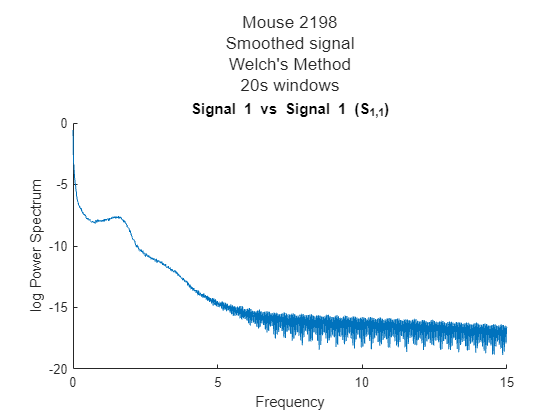

noverlap = f*10;
L = f*20;
PSD = cell(nmice, ntraces, nmice, ntraces);
angular_frequencies = cell(nmice, ntraces, nmice, ntraces);

for mouse = 1:nmice
    for trace = 1:ntraces
        for cross_mouse = 1:nmice
            for cross_trace = 1:ntraces

                signal1 = data(:, mouse, trace);
                signal2 = data(:, cross_mouse, cross_trace);
                
                % Check the lengths of the signals and zero-pad the shorter signal if necessary
                len1 = length(signal1);
                len2 = length(signal2);
                if len1 < len2
                    signal1 = [signal1; zeros(len2-len1, 1)];
                elseif len2 < len1
                    signal2 = [signal2; zeros(len1-len2, 1)];
                end

                [PSD{mouse, trace, cross_mouse, cross_trace},...
                angular_frequencies{mouse, trace, cross_mouse, cross_trace}] =...
                cpsd(signal1, signal2, hamming(L), noverlap, [], f);
   
            end
        end
    end
end



for mouse = 1:nmice
    figure;
    t = tiledlayout(ntraces, ntraces);
    for trace = 1:ntraces
        for cross_trace = 1:ntraces
            nexttile;
            hold on
            plot((angular_frequencies{mouse, trace, mouse, cross_trace}/(2*pi)), log(abs(PSD{mouse, trace, cross_mouse, cross_trace})))
            title(sprintf('%s vs %s (S_{%d,%d})',...
                signal_names{trace},signal_names{cross_trace},trace,cross_trace))
            ylabel("log Power Spectrum")
            xlabel('Frequency')
            xlim([0,15])
            hold off
        
        end
    end
    PSDtitle = {mouse_names{mouse}, 'Smoothed signal', "Welch's Method" , '20s windows'};
    sgtitle(PSDtitle)
end